***Integrantes***:

- Naysla tatiana torres Cortes

# MÉTODO EULER MEJORADO

**Ejercicio 1**

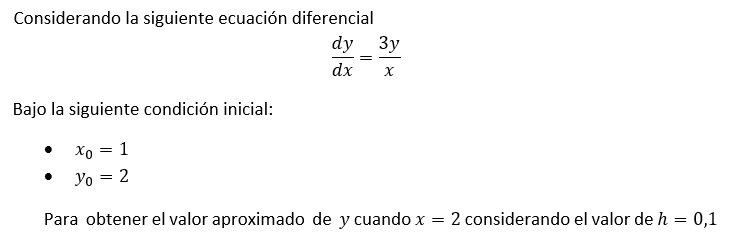

%datos iniciales
x0=1;
y0=1;
x=2;
h=0,1;

h = 0

n=11; % se toma como 11 para que en ese punto el valor de x sea 2 y se 
%obtenga la respuesta requerida
%Paso 1 determinar la tabla
strcat('x0=',num2str(x0),' y0=', num2str(y0),' x=', num2str(x),' y=?')

ans = 'x0=1 y0=1 x=2 y=?'

%Paso 2 Determinar el valor de h, nos lo dan desde el inicio, no se hace
%uso de la fórmula
h=0.1

h = 0.1000

%Paso 3 Identificar por cada paso n x sub i
strcat('_n_','_xi_')

ans = '_n__xi_'

 xi =x0;
for i = 1:n   
    strcat(' ',num2str(i),' _ _', num2str(xi))
    xi=xi+h;
end

ans = '1 _ _1'

ans = '2 _ _1.1'

ans = '3 _ _1.2'

ans = '4 _ _1.3'

ans = '5 _ _1.4'

ans = '6 _ _1.5'

ans = '7 _ _1.6'

ans = '8 _ _1.7'

ans = '9 _ _1.8'

ans = '10 _ _1.9'

ans = '11 _ _2'

%Paso 4 identificar yi , y' por cada n
yi =y0

yi = 1

xi =x0

xi = 1

f=EvaluarFuncion(xi,yi)

f = 3

xi_1 = xi+h;
yi_1 = Valoryi(yi, f, h);
f2=EvaluarFuncion(xi_1,yi_1)

f2 = 3.5455

f3 = EvaluarFuncionFinal(yi,h,f,f2) 

f3 = 1.3273

strcat('_n_ xi _ yi _ f_ yi_1 _ xi_1 _ f2 _ f3 _')

ans = '_n_ xi _ yi _ f_ yi_1 _ xi_1 _ f2 _ f3 _'

for j = 1:n 
    
   %Se concatenan los valores
    strcat(' ',num2str(j),' _ ', num2str(xi),' _ ', num2str(yi),' _ ',num2str(f),' _ ',num2str(yi_1) ,' _ ',num2str(xi_1),' _ ',num2str(f2),' _ ',num2str(f3) )
   if (j~=11)
        xi=xi+h;
        yi= f3;
        xi_1 = xi+h;
        f2=EvaluarFuncion(xi_1,yi_1);
        f=EvaluarFuncion(xi,yi);
        f3 = EvaluarFuncionFinal(yi,h,f,f2);
      end 
end

ans = '1 _1 _1 _3 _1.3 _1.1 _3.5455 _1.3273'

ans = '2 _1.1 _1.3273 _3.6198 _1.3 _1.2 _3.25 _1.6708'

ans = '3 _1.2 _1.6708 _4.1769 _1.3 _1.3 _3 _2.0296'

ans = '4 _1.3 _2.0296 _4.6837 _1.3 _1.4 _2.7857 _2.4031'

ans = '5 _1.4 _2.4031 _5.1495 _1.3 _1.5 _2.6 _2.7906'

ans = '6 _1.5 _2.7906 _5.5811 _1.3 _1.6 _2.4375 _3.1915'

ans = '7 _1.6 _3.1915 _5.984 _1.3 _1.7 _2.2941 _3.6054'

ans = '8 _1.7 _3.6054 _6.3625 _1.3 _1.8 _2.1667 _4.0318'

ans = '9 _1.8 _4.0318 _6.7197 _1.3 _1.9 _2.0526 _4.4705'

ans = '10 _1.9 _4.4705 _7.0586 _1.3 _2 _1.95 _4.9209'

ans = '11 _2 _4.9209 _7.3813 _1.3 _2.1 _1.8571 _5.3828'

%Respuesta
strcat('La respuesta es:')

ans = 'La respuesta es:'

strcat('cuando X es_', num2str(xi),' El Valor aproximado de y es_ ', num2str(f))

ans = 'cuando X es_2 El Valor aproximado de y es_7.3813'

***FUNCIONES***  

function f = EvaluarFuncion(x,y)    
    f = (3*y)/x;
end
function f3 = EvaluarFuncionFinal(yi,h,f,f2)    
    f3= yi +(h/2)*(f+f2);
end
function [y]=Valoryi(yi, f, h) 
    y = yi+ (f*h);
end


